# Modulation Generator

8 digital and 3 analog modulation types: 

- Binary phase shift keying (BPSK)

- Quadrature phase shift keying (QPSK)

- 8-ary phase shift keying (8-PSK)

- 16-ary quadrature amplitude modulation (16-QAM)

- 64-ary quadrature amplitude modulation (64-QAM)

- 4-ary pulse amplitude modulation (PAM4)

- Gaussian frequency shift keying (GFSK)

- Continuous phase frequency shift keying (CPFSK)

- Broadcast FM (B-FM)

- Double sideband amplitude modulation (DSB-AM)

- Single sideband amplitude modulation (SSB-AM)

Generate several PAM4 frames that are impaired with Rician multipath fading, center frequency and sampling time drift, and AWGN. Use following function to generate synthetic signals to test the CNN. Then use the CNN to predict the modulation type of the frames.

- [randi](docid:matlab_ref#buf2csg):  Generate random bits

- [pammod:](docid:comm_ref#a1042480014b1) PAM4-modulate the bits

- [rcosdesign](docid:signal_ref#bt00vcn): Design a square-root raised cosine pulse shaping filter

- [filter](docid:matlab_ref#bt_vs4t-1): Pulse shape the symbols

- [comm.RicianChannel](docid:comm_ref#btzx8bh-1): Apply Rician multipath channel

- [comm.PhaseFrequencyOffset](docid:comm_ref#bsnfizs_4): Apply phase and/or frequency shift due to clock offset

- [interp1](docid:matlab_ref#btwp6lt-1): Apply timing drift due to clock offset

- [awgn](docid:comm_ref#fp1221678): Add AWGN

Each frame is 1024 samples long and has a sample rate of 200 kHz. For digital modulation types, eight samples represent a symbol. The network makes each decision based on single frames rather than on multiple consecutive frames (as in video). Assume a center frequency of 902 MHz and 100 MHz for the digital and analog modulation types, respectively.

To run this example quickly, use the trained network and generate a small number of training frames. To train the network on your computer, choose the "Train network now" option (i.e. set trainNow to true).

modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
   "16QAM", "64QAM", "PAM4", "GFSK", "CPFSK", ...
   "B-FM", "DSB-AM", "SSB-AM"]);

transDelay = 50;
numFramesPerModType = 1;
sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
fs = 600e3;             % Sample rate
dataDirectory = fullfile(pwd);
disp("Current file directory is " + dataDirectory)

Current file directory is /Users/josea/Research/siwn-node/network/Matlab


### Waveform Generation

Create a loop that generates frames for each modulation type and stores the frames with their corresponding labels in MAT files. 

00:00:00 - Generating BPSK frames


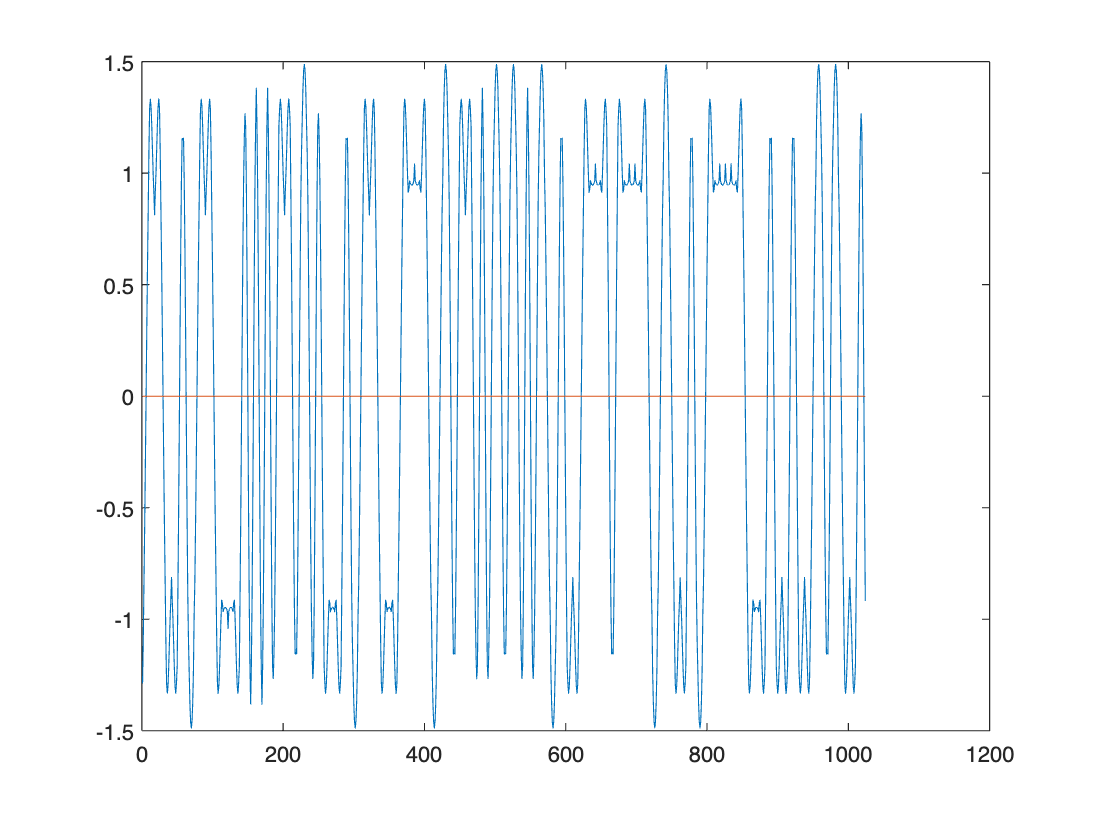

filename = "data_BPSK.dat"

ans = 2048

00:00:00 - Generating QPSK frames


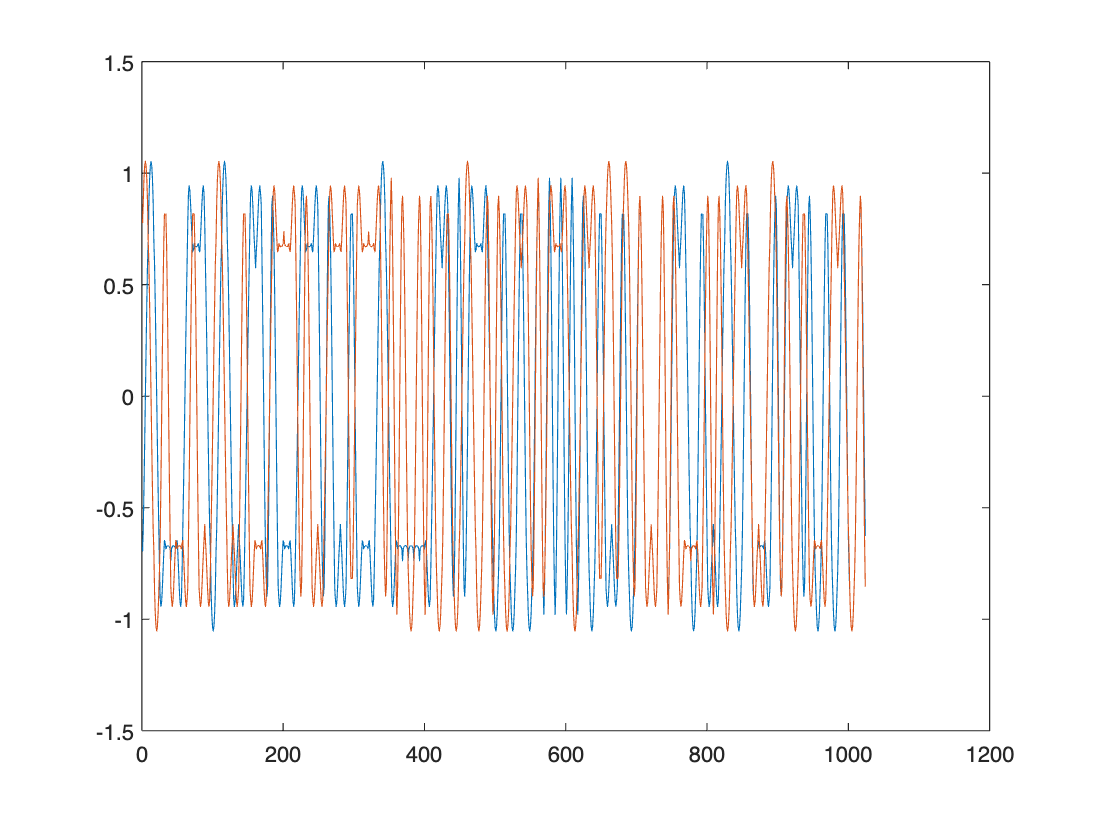

filename = "data_QPSK.dat"

ans = 2048

00:00:00 - Generating 8PSK frames


filename = "data_8PSK.dat"

ans = 2048

00:00:00 - Generating 16QAM frames


filename = "data_16QAM.dat"

ans = 2048

00:00:00 - Generating 64QAM frames


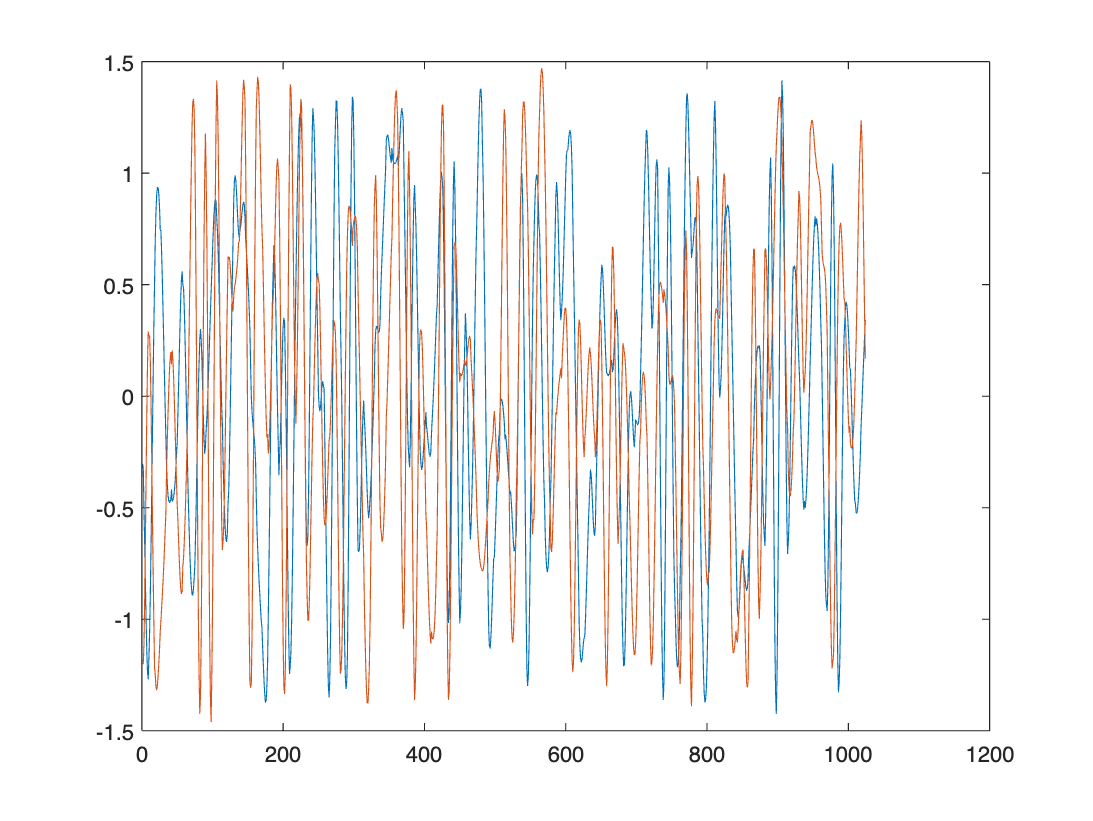

filename = "data_64QAM.dat"

ans = 2048

00:00:00 - Generating PAM4 frames


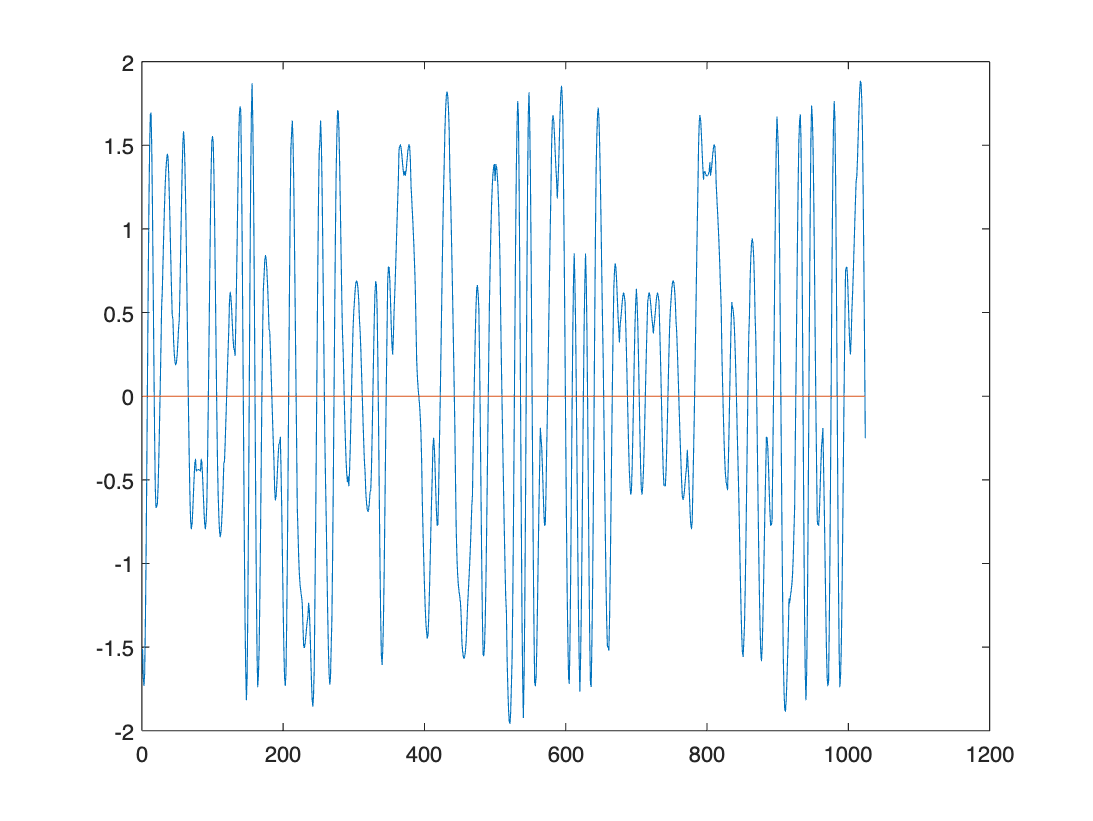

filename = "data_PAM4.dat"

ans = 2048

00:00:00 - Generating GFSK frames


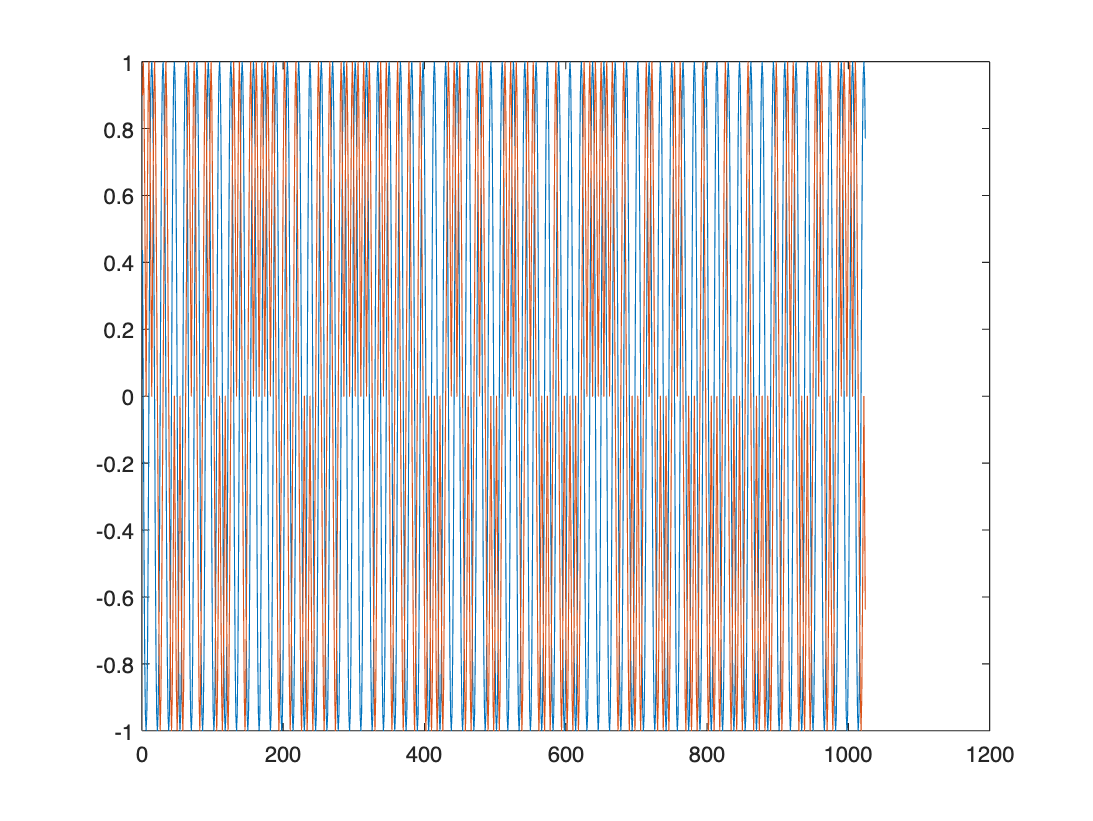

filename = "data_GFSK.dat"

ans = 2048

00:00:00 - Generating CPFSK frames


filename = "data_CPFSK.dat"

ans = 2048

00:00:00 - Generating B-FM frames


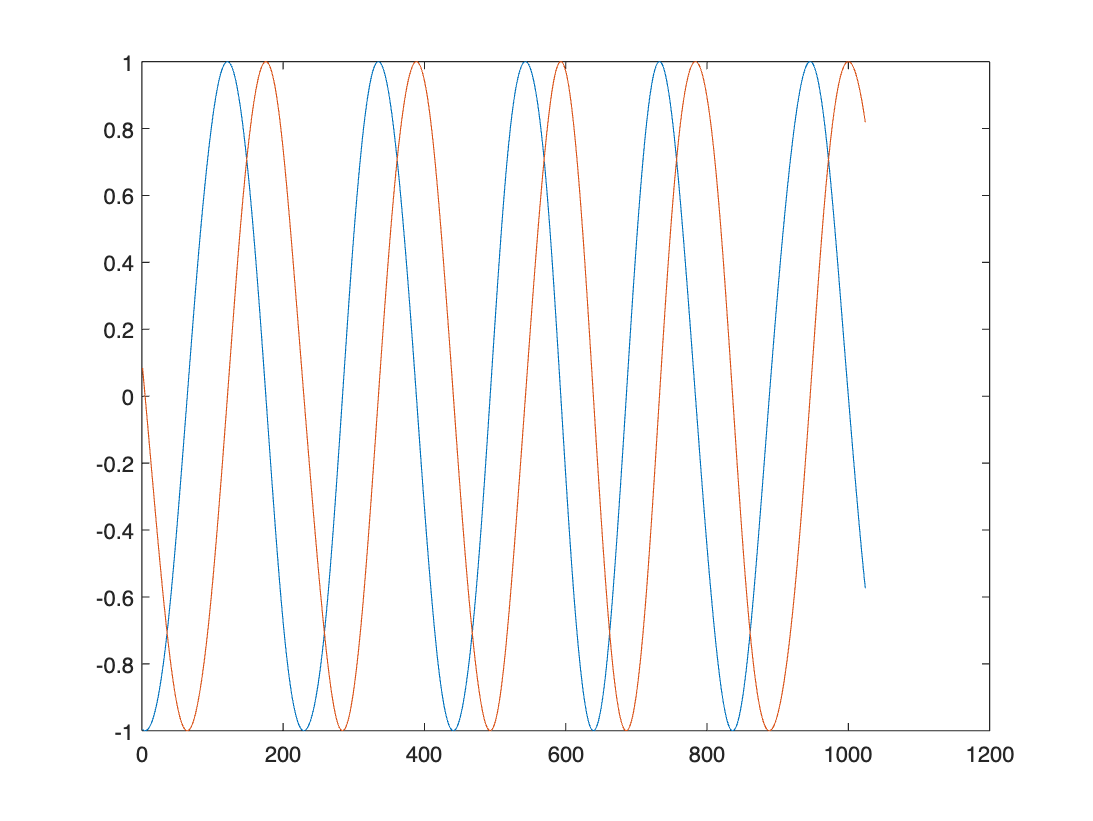

filename = "data_B-FM.dat"

ans = 2048

00:00:00 - Generating DSB-AM frames


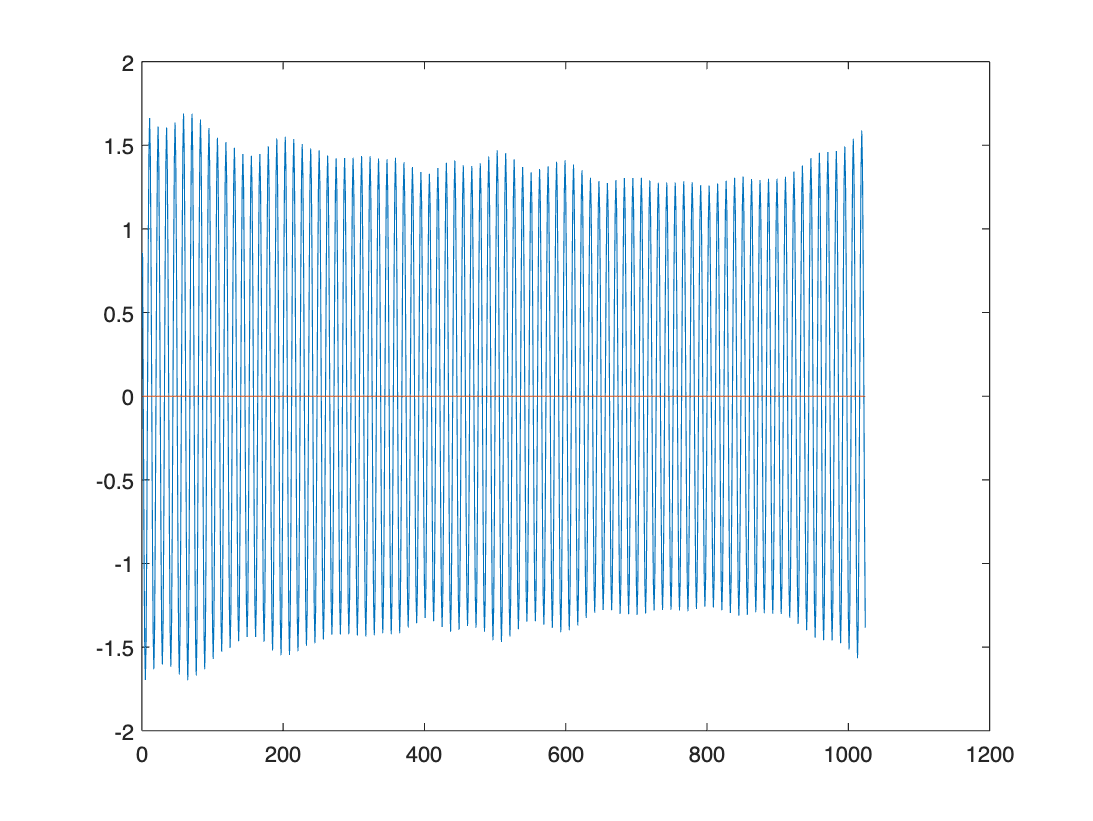

filename = "data_DSB-AM.dat"

ans = 2048

00:00:00 - Generating SSB-AM frames


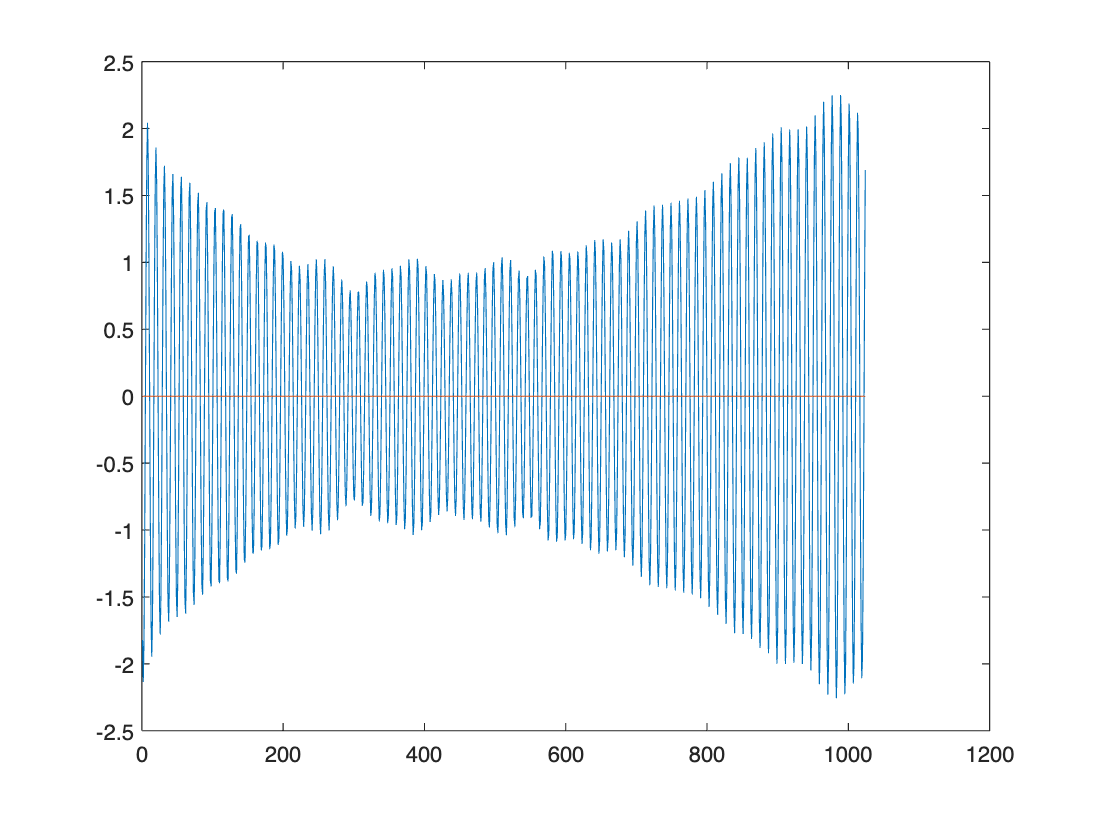

filename = "data_SSB-AM.dat"

ans = 2048

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(1235)
tic

numModulationTypes = length(modulationTypes);
fileNameRoot = "frame";

% Define the dimensions of your data and labels
X = numFramesPerModType*numModulationTypes; % Number of sets
N = spf; % Number of IQ samples per frame
num_features = 2; % Two features for the IQ data (real and imaginary parts)
% if ~dataFilesExist
%   disp("Generating data and saving in data files...")
%   [success,msg,msgID] = mkdir(dataDirectory);
%   if ~success
%     error(msgID,msg)
%   end
for modType = 1:numModulationTypes
    elapsedTime = seconds(toc);
    elapsedTime.Format = 'hh:mm:ss';
    fprintf('%s - Generating %s frames\n', ...
      elapsedTime, modulationTypes(modType))
    
    label = modulationTypes(modType);
    numSymbols = (numFramesPerModType / sps);
    dataSrc = helperModClassGetSource(modulationTypes(modType), sps, 2*spf, fs);
    modulator = helperModClassGetModulator(modulationTypes(modType), sps, fs);
    % Generate random data
    x = dataSrc();
    % Modulate
    rxSamples = modulator(x);
    % Remove transients from the beginning, trim to size, and normalize
    data = helperModClassFrameGenerator(rxSamples, spf, spf, transDelay, sps);
    x_axis = 1:length(data);
    figure(modType*2+1);
    plot(x_axis,real(data),x_axis,imag(data));
    filename = append(string(modulationTypes(modType)),".dat")
    write_complex_binary (data, filename)
end